## Import BIDS dataset

**Run 'eeglab' from the folder containing the eeglab codes. This will add all the relevant EEGLAB functions and directories to path.**

eeglab: options file is ~/eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "bids-matlab-tools" v6.0 (see >> help eegplugin_bids)
EEGLAB: adding "clean_rawdata" v2.5 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit)


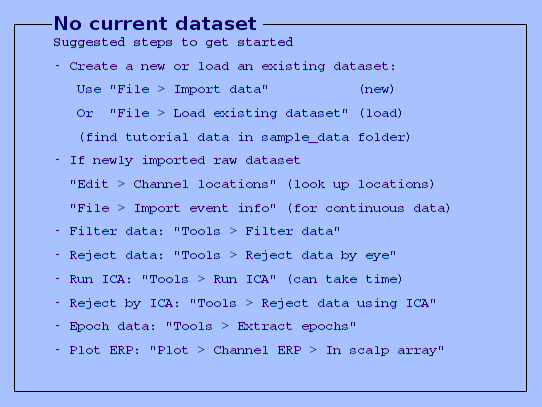

You are using the latest version of EEGLAB.


eeglab;

**Steps:**

- **Add ds003061 and subfolders to path**

- **Make ds003061 current directory. **

- **Then run the following code:**

filepath = fileparts(which('participants.tsv')); % assumes if this BIDS file is present, it belongs to ds003061
if isempty(filepath)
    error('Cannot find ds003061 BIDS dataset, download it from OpenNeuro.org, uncompress it, and add it to your Matlab path')
end

The function pop_importbids() imports a BIDS format folder structure into an EEGLAB study. 

If 'bidsevent' is 'on' then events will be imported from the BIDS .tsv event file and events in the raw binary EEG files will be ignored. Similarly 'bidschanloc', 'on' will import channel locations from BIDS .tsv file and ignore any locations in raw EEG files. The 'studyName' field lets you specify the name of the newly created STUDY.

[STUDY, ALLEEG] = pop_importbids(filepath,'bidsevent','off','bidschanloc','off','studyName','Auditory_Oddball_Task');

Importing file: /home/user1/Documents/Manisha/eeglab/ds003061/sub-001/eeg/sub-001_task-P300_run-1_eeg.set
pop_loadset(): loading file /home/user1/Documents/Manisha/eeglab/ds003061/sub-001/eeg/sub-001_task-P300_run-1_eeg.set ...
The EEG file has channel locations associated with it, we are keeping them
Saving dataset...
Importing file: /home/user1/Documents/Manisha/eeglab/ds003061/sub-001/eeg/sub-001_task-P300_run-2_eeg.set
pop_loadset(): loading file /home/user1/Documents/Manisha/eeglab/ds003061/sub-001/eeg/sub-001_task-P300_run-2_eeg.set ...
The EEG file has channel locations associated with it, we are keeping them
Saving dataset...
Importing file: /home/user1/Documents/Manisha/eeglab/ds003061/sub-001/eeg/sub-001_task-P300_run-3_eeg.set
pop_loadset(): loading file /home/user1/Documents/Manisha/eeglab/ds003061/sub-001/eeg/sub-001_task-P300_run-3_eeg.set ...
The EEG file has channel locations associated with it, we are keeping them
Saving dataset...
Importing file: /home/user1/Documents

## Process dataset

Loop across datasets and process data epochs. The type of epoch and any other interesting field is in epoch_type.datasetinfo.trialinfo; all fields in this structure will be saved as different columns. Pass a label filename which will be updated by mat2tiff_EEG.

CURRENTSTUDY = 1;
for CURRENTSET = 1:length(ALLEEG)
    CURRENTSET
    EEG =  ALLEEG(CURRENTSET);
    EEGepoch = pop_epoch(EEG, unique({EEG.event.type}), [-1 2]);
    mat2tiff_extendedLabel_EEG(EEGepoch,'Auditory_Oddball_Task_labels_s3.txt','s3://openneuro.org/ds003061')
end

CURRENTSET = 1

pop_epoch():863 epochs selected
Epoching...
pop_epoch():861 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 2

pop_epoch():862 epochs selected
Epoching...
pop_epoch():859 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 3

pop_epoch():860 epochs selected
Epoching...
pop_epoch():858 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 4

pop_epoch():812 epochs selected
Epoching...
pop_epoch():810 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 5

pop_epoch():807 epochs selected
Epoching...
pop_epoch():805 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs


CURRENTSET = 6

pop_epoch():799 epochs selected
Epoching...
pop_epoch():797 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
